# Métodos de Runge-Kutta

**Sesión-04-Solución de Sistemas de EDO para resolver circuitos RLC en Serie**

**Ej.-** Diseñe una herramienta en Matlab para simular el comportamiento de la ***Carga*** y la ***Corriente*** de un **circuito RLC** en serie para diferentes valores de **R,L,C **y **E(t)** constante proporcionados por el usuario. Comprueba tu herramienta con un escenario durante** 5 segundos** con un tamaño de paso de **0.5 segs **con los valores iniciales siguientes para el circuito, suponiendo un circuito inicial descargado:

- **R=2 Ohms**

- **L=3 Henrios**

- **C=1 Faradio**

- **E(t)=8 volts (constante)**

#### Nombre: Daniel Alfredo Barreras Meraz     

#### Fecha: 13 de junio de 2023

#### Matrícula: A01254805

**Solución.- Método de RK Cuarto orden**:

clear

% Parámetros del circuito -----------------------------------------
R=6;
L=3;
C=0.2;
Et=24;


% Límites de tiempo y paso
li=0;
ls=9;
h=0.5;

% Llamada a la función rk4Orden para calcular los resultados
[T, x, y1, y2] = calcularLRC(R, L, C, Et, li, ls, h);

% Mostrar la tabla de resultados
disp(T)

    Tiempo       Carga        Corriente 
    ______    ___________    ___________

       0                0              0
     0.5           2.3611         2.3611
       1           2.6248         2.6248
     1.5           2.0514         2.0514
       2           1.3171         1.3171
     2.5          0.71127        0.71127
       3           0.3073         0.3073
     3.5         0.080556       0.080556
       4        -0.023236      -0.023236
     4.5        -0.055397      -0.055397
       5        -0.053057      -0.053057
     5.5         -0.03865       -0.03865
       6        -0.023493      -0.023493
     6.5        -0.011931      -0.011931
       7       -0.0046408     -0.0046408
     7.5      -0.00078009    -0.00078009
       8       0.00083613     0.00083613
     8.5        0.0012158      0.0012158
       9        0.0010447      0.0010447



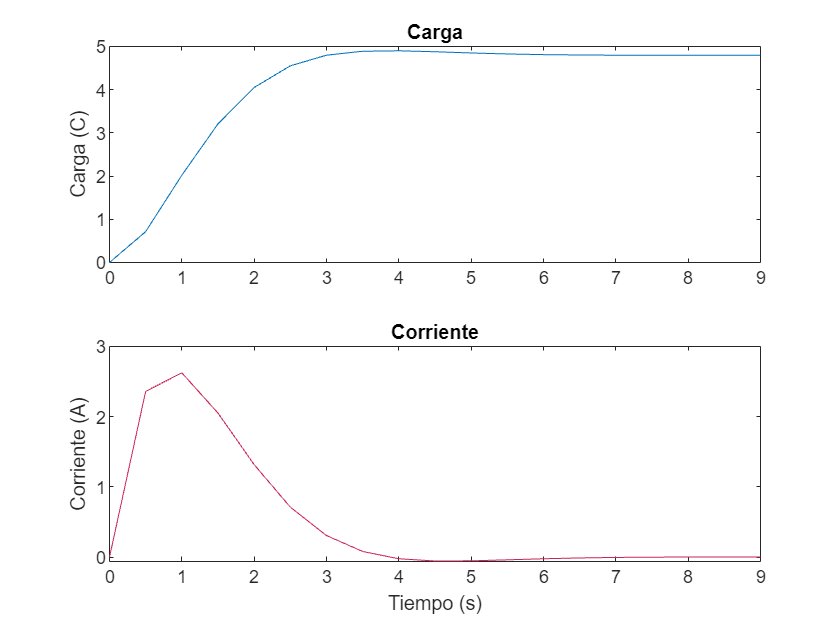


% Crear dos subgráficas para mostrar la carga y la corriente
subplot(2, 1, 1)
plot(x, y1)
ylabel('Carga (C)')
title('Carga')

subplot(2, 1, 2)
plot(x, y2, 'Color', "#cc2456")
xlabel('Tiempo (s)')
ylabel('Corriente (A)')
title('Corriente')

### Función que resuelve el circuito LRC utilizando Runge-Kutta 4

function [T, x, y1, y2] = calcularLRC(R, L, C, Et, li, ls, h)
    % Método de RK4Orden
    % R, L, C, Et - Parámetros del circuito
    % li - Limite inferior en el tiempo
    % ls - Limite superior en el tiempo
    % h - Paso

    % Ecuaciones Diferenciales Ordinarias dy/dx=f(x,y) a resolver
    f1 = @(x,y1,y2) y2;
    f2 = @(x,y1,y2) (Et-y2*R-y1/C)/L;

    % Condiciones iniciales
    x(1) = 0;
    y1(1) = 0;
    y2(1) = 0;

    % Método de RK4Orden
    n = (ls-li)/h;
    for i=1:n
        k11 = h*f1(x(i),y1(i),y2(i));
        k12 = h*f2(x(i),y1(i),y2(i));
        k21 = h*f1(x(i)+h/2,y1(i)+k11/2,y2(i)+k12/2);
        k22 = h*f2(x(i)+h/2,y1(i)+k11/2,y2(i)+k12/2);
        k31 = h*f1(x(i)+h/2,y1(i)+k21/2,y2(i)+k22/2);
        k32 = h*f2(x(i)+h/2,y1(i)+k21/2,y2(i)+k22/2);
        k41 = h*f1(x(i)+h,y1(i)+k31,y2(i)+k32);
        k42 = h*f2(x(i)+h,y1(i)+k31,y2(i)+k32);
        x(i+1) = x(i)+h;
        y1(i+1) = y1(i)+(k11+2*k21+2*k31+k41)/6;
        y2(i+1) = y2(i)+(k12+2*k22+2*k32+k42)/6;
    end

    % Crear una tabla con los resultados
    T = array2table([x' y2' y2'], 'VariableNames', {'Tiempo', 'Carga', 'Corriente'});
end